%{
Data: Auto MPG Data Set  
URL: http://archive.ics.uci.edu/ml/datasets/Auto+MPG

# Intro  
This dataset was taken from the StatLib library which is maintained at Carnegie Mellon University. The dataset was used in the 1983 American Statistical Association Exposition. 

From this dataset,we obtain the multiple regression analasis to help us finding out the strength of the
relationship between the dependent variable mpg and the predictors to the
relationship. 
To obtain the coefficient estimates, we will use least-squares method to minimizes the summed square of residuals.

# Attribute Information:
1: mpg: continuous (y)
2. cylinders: multi-valued discrete ($x_1$)
3. displacement: continuous ($x_2$)  
4. horsepower: continuous ($x_3$)  
5. weight: continuous ($x_4$)  
6. acceleration: continuous ($x_5$)  
7. model year: multi-valued discrete ($x_6$)  
8. origin: multi-valued discrete)($x_7$)  
9. car_name :  string (unique for each instance).
%}
%data = readtable("auto-mpg.csv");
data = readtable("/Users/juliejiang/Desktop/auto-mpg.csv");
data.Properties.VariableNames = {'mpg' 'cylinders' 'displacement' 'horsepower' 'weight' 'acceleration' 'model_year' 'origin' 'car_name'}

data = 398×9 table
    mpg    cylinders    displacement    horsepower    weight    acceleration    model_year    origin              car_name           
    ___    _________    ____________    __________    ______    ____________    __________    ______    _____________________________

    18         8            307            130         3504           12            70          1       {'chevrolet chevelle malibu'}
    15         8            350            165         3693         11.5            70          1       {'buick skylark 320'        }
    18         8            318            150         3436           11            70          1       {'plymouth satellite'       }
    


% polyfit(data.horsepower,data.mpg,1)
model = fitlm(data, 'mpg ~ cylinders+ displacement+ horsepower + weight+acceleration+ model_year+origin')

model = Linear regression model:
    mpg ~ 1 + cylinders + displacement + horsepower + weight + acceleration + model_year + origin

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                    _________    __________    _______    __________

    (Intercept)       -17.218        4.6443    -3.7074    0.00024018
    cylinders        -0.49338       0.32328    -1.5261        0.1278
    displacement     0.019896     0.0075151     2.6474     0.0084446
    horsepower      -0.016951      0.013787    -1.2295       0.21963
    weight          -0.006474    0.00065205    -9.9288     7.875e-21
    acceleration     0.080576      0.098845    0.81517       0.41548
    model_year        0.75077      0

%%% cylinders, horsepower, acceleration  are not significant. 
%scatter(data.weight + data.model_year + data.origin,data.mpg)
fitted_model = fitlm(data, 'mpg ~ displacement + weight')

fitted_model = Linear regression model:
    mpg ~ 1 + displacement + weight

Estimated Coefficients:
                     Estimate         SE         tStat       pValue   
                    __________    __________    _______    ___________

    (Intercept)           43.9        1.1591     37.873    1.5091e-133
    displacement     -0.016358     0.0057523    -2.8438      0.0046899
    weight          -0.0057977    0.00070827    -8.1858     3.7699e-15


Number of observations: 398, Error degrees of freedom: 395
Root Mean Squared Error: 4.31
R-squared: 0.698,  Adjusted R-Squared: 0.696
F-statistic vs. constant model: 456, p-value = 2.03e-103

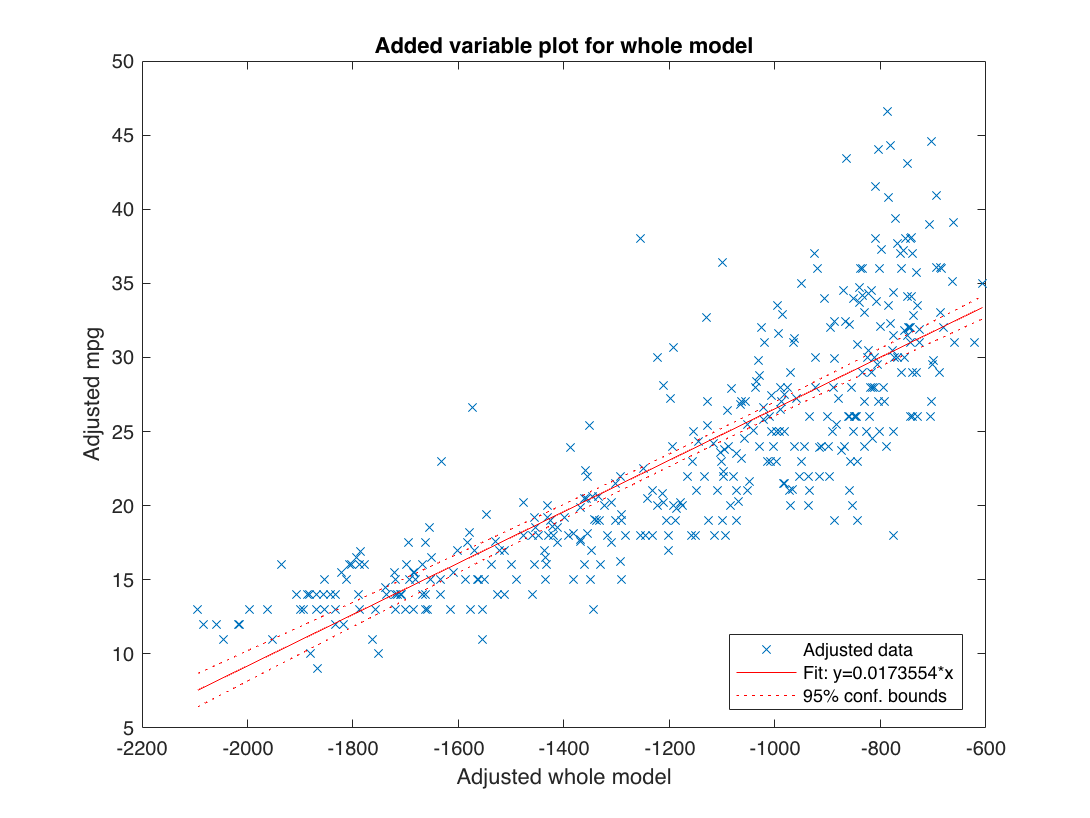


plot(fitted_model)

%----------------------------------------------
% From the plot, we can see that the trend is not linear. Thus try adding
% polynomial factors.
x = [data.cylinders,data.displacement,data.horsepower,data.weight,data.acceleration,data.model_year,data.origin]

x = 	1.0e+03 *

    0.0080    0.3070    0.1300    3.5040    0.0120    0.0700    0.0010
    0.0080    0.3500    0.1650    3.6930    0.0115    0.0700    0.0010
    0.0080    0.3180    0.1500    3.4360    0.0110    0.0700    0.0010
    0.0080    0.3040    0.1500    3.4330    0.0120    0.0700    0.0010
    0.0080    0.3020    0.1400    3.4490    0.0105    0.0700    0.0010
    0.0080    0.4290    0.1980    4.3410    0.0100    0.0700    0.0010
    0.0080    0.4540    0.2200    4.3540    0.0090    0.0700    0.0010
    0.0080    0.4400    0.2150    4.3120    0.0085    0.0700    0.0010
    0.0080    0.4550    0.2250    4.4250    0.0100    0.0700    0.0010
    0.0080    0.3900    0.1900    3.8500    0.0085    0.0700    0.0010


T = [0 0 0 0 0 0 0 0; 1 0 0 0 0 0 0 0; 0 1 0 0 0 0 0 0; 0 0 1 0 0 0 0 0; 0 0 0 1 0 0 0 0; 0 0 0 0 1 0 0 0; 0 0 0 0 0 1 0 0; 0 0 0 0 0 0 1 0;
     1 1 0 0 0 0 0 0; 1 0 1 0 0 0 0 0; 1 0 0 1 0 0 0 0; 1 0 0 0 1 0 0 0; 1 0 0 0 0 1 0 0; 1 0 0 0 0 0 1 0;
     0 1 1 0 0 0 0 0; 0 1 0 1 0 0 0 0; 0 1 0 0 1 0 0 0; 0 1 0 0 0 1 0 0; 0 1 0 0 0 0 1 0;
     0 0 1 1 0 0 0 0; 0 0 1 0 1 0 0 0; 0 0 1 0 0 1 0 0; 0 0 1 0 0 0 1 0;
     0 0 0 1 1 0 0 0; 0 0 0 1 0 1 0 0; 0 0 0 1 0 0 1 0;
     0 0 0 0 1 1 0 0; 0 0 0 0 1 0 1 0;
     0 0 0 0 0 1 1 0;
     2 0 0 0 0 0 0 0; 
     0 2 0 0 0 0 0 0; 
     0 0 2 0 0 0 0 0;
     0 0 0 2 0 0 0 0;
     0 0 0 0 2 0 0 0;
     0 0 0 0 0 2 0 0;
     0 0 0 0 0 0 2 0;]

T =      0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     1     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     1     1     0     0     0     0     0     0
     1     0     1     0     0     0     0     0


modelc1 = fitlm(x,data.mpg,T)

modelc1 = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x1*x4 + x1*x5 + x1*x6 + x1*x7 + x2*x3 + x2*x4 + x2*x5 + x2*x6 + x2*x7 + x3*x4 + x3*x5 + x3*x6 + x3*x7 + x4*x5 + x4*x6 + x4*x7 + x5*x6 + x5*x7 + x6*x7 + x1^2 + x2^2 + x3^2 + x4^2 + x5^2 + x6^2 + x7^2

Estimated Coefficients:
                    Estimate          SE          tStat        pValue  
                   ___________    __________    _________    __________

    (Intercept)         383.93        100.59       3.8169    0.00015932
    x1                  8.4359        8.6599      0.97414       0.33065
    x2                -0.59029        0.1931       -3.057     0.0024049
    x3                 0.20585         0.397      0.51852       0.60442
    x4                0.016783      0.018567      0.90393  

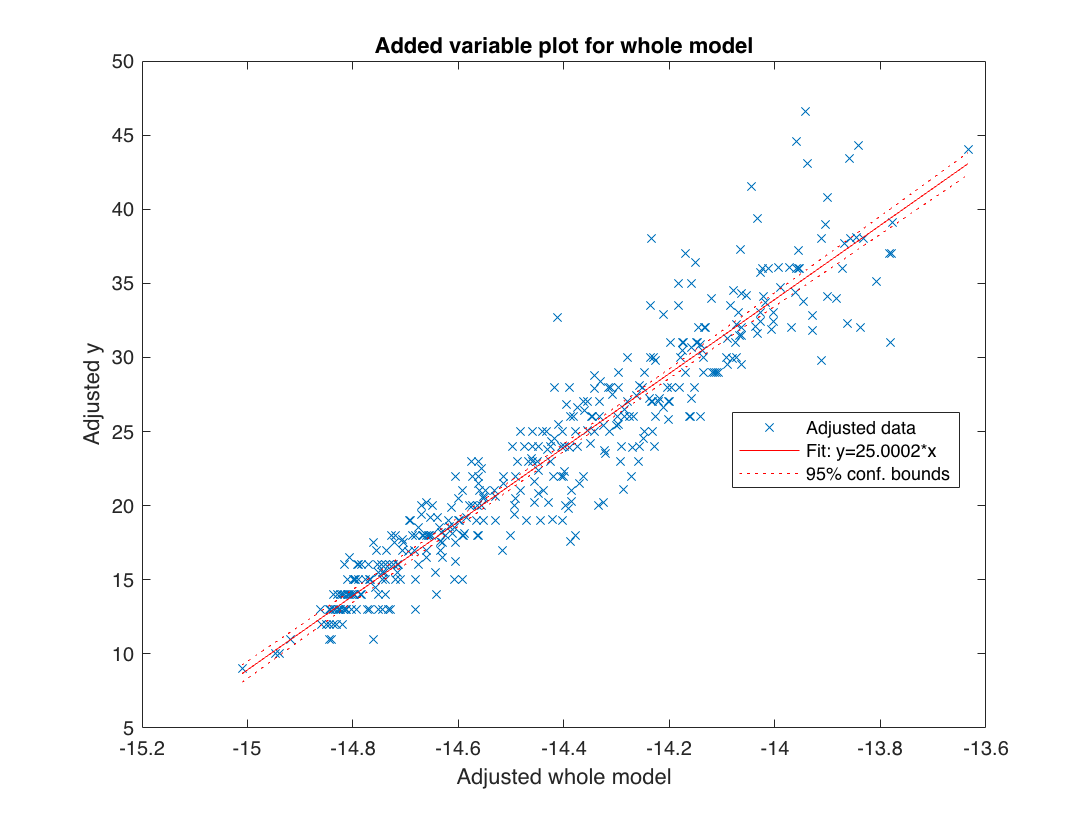

plot(modelc1)

% Now our line fits the trend better. 
%Here, we have so many parameter and is thus involved in multiple testing.
%This means that we have a higher chance of typeI error. Thus, we will use
%Bonferroni correction, which we use alpha = 0.05/# of parameters to find
%the sigfinicance parameters.

% with significance level of 0.05/36 = 0.001388889, 
%--------------------------------------------

% So now we have the model 
% y = a + bx_1 + bx_2 + bx_3, which equals 
% mpg = a + b weight + c model_year + d origin
a2 = table2array(data(:,{'displacement'})); 
a3 = table2array(data(:,{'weight'})); 
a4 = table2array(data(:,{'model_year'}));
a5 = table2array(data(:,{'origin'}));
sz = [height(a2) 1]

sz =    398     1


a1 = ones(sz)

a1 =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


A = [a1 a2 a3 a4 a5]

A = 	1.0e+03 *

    0.0010    0.3070    3.5040    0.0700    0.0010
    0.0010    0.3500    3.6930    0.0700    0.0010
    0.0010    0.3180    3.4360    0.0700    0.0010
    0.0010    0.3040    3.4330    0.0700    0.0010
    0.0010    0.3020    3.4490    0.0700    0.0010
    0.0010    0.4290    4.3410    0.0700    0.0010
    0.0010    0.4540    4.3540    0.0700    0.0010
    0.0010    0.4400    4.3120    0.0700    0.0010
    0.0010    0.4550    4.4250    0.0700    0.0010
    0.0010    0.3900    3.8500    0.0700    0.0010


b = table2array(data(:,{'mpg'}));
A_1 = transpose(A) * A;
A_plus = inv(A_1) *  transpose(A);
x = A_plus * b

x =   -18.5449
    0.0064
   -0.0067
    0.7726
    1.2507
